%T2.3-1
clc; clear; 
x = [6 5 10];
y = [3 9 8];



sum = x + y 

sum =      9    14    18


w = x.*y 

w =     18    45    80


z = y.*x

z =     18    45    80



%T2.3_2
clc; clear;

A = [6 4; 5 3];
B = [5 2; 7 9];

C = A+B

C =     11     6
    12    12


w = A.*B

w =     30     8
    35    27


z = B.*A 

z =     30     8
    35    27



%T2.3-3
clc; clear;

x = [ 6 5 10];
y = [ 3 9 8];

w = x./y

w =     2.0000    0.5556    1.2500


z = y./x

z =     0.5000    1.8000    0.8000



%T2.3-4 
clc; clear; 

A = [6 4 ; 5 3];
B = [5 2 ; 7 9];

C = A./B

C =     1.2000    2.0000
    0.7143    0.3333


D = B./A 

D =     0.8333    0.5000
    1.4000    3.0000


E = A.\B

E =     0.8333    0.5000
    1.4000    3.0000


F = B.\A

F =     1.2000    2.0000
    0.7143    0.3333


% C = F , D = E 

%T2.3-5
clc; clear;
A = [21 27; -18, 8];
B = [-7, -3; 9,4];

c = A.*B

c =   -147   -81
  -162    32


d = A./B

d =     -3    -9
    -2     2


e = B.^3

e =   -343   -27
   729    64



%T2.4-1 
clc; clear;

x = [6;5;3];
y = [2,8,7];

w = x*y;
z = y*x;

if w == z 
    disp('same')
else
    disp('nope')
end 

nope



%T2.4-2 
clc; clear;

u = [6 -8 3];
w = [5 3 -4];

a = sum(u.*w)

a = -6



%T2.4-3 
clc; clear; 

A = [7 4; -3 2; 5 9];
B = [1 8 ; 7 6];

c = A*B

c =     35    80
    11   -12
    68    94



%T2.4-4 
clc; clear; 
a = [ 4 3; 8 -2];
b = [ 23; 6]

b =     23
     6



c = a\b 

c =      2
     5



%T2.4-5 
clc; clear;
a = [ 4 -2; 3 5];
b = [16; -1];

c = a\b 

c =      3
    -2



%T2.4-6 
clc; clear;
a = [ 6 -4 8 ; -5 -3 7; 14 9 -5];
b = [112; 75; -67];

c = a\b

c =     2.0000
   -5.0000
   10.0000



%T2.5-1 
clc; clear; 
c = roots([1,13,52,6])

c =   -6.4406 + 2.9980i
  -6.4406 - 2.9980i
  -0.1189 + 0.0000i


poly(c)

ans =     1.0000   13.0000   52.0000    6.0000



%T2.5-2
clc; clear; 

a = [ 20 -7 5 10];
b = [ 4 12 -3 ];
c = conv(a,b)

c =     80   212  -124   121   105   -30



%T2.5-3 
clc; clear; 
a = [12 5 -2 3];
b = [3 -7 4];
[q,r] = deconv(a,b)

q =      4    11


r =      0     0    59   -41



%T2.5-4 
clc;clear; 

a = [6,4, 0, -5];
b = [12, -7, 3, 9];

val_num = polyval(a, 2);
val_den = polyval(b, 2);

% 최종 결과 계산
result = val_num / val_den

result = 0.7108

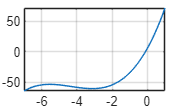


%T2.5-5 

a = [1 13 52 6];
fplot(@(x) polyval(a, x), [-7, 1]) 
grid on


%T2.7-1 
clc; clear; 

student = struct( ...
    'name', 'Alfred E. Newman', ...
    'SN', '0003456', ...
    'e_mail', 'newmana@myschool.edu', ...
    'test', [55, 45, 58])

student = 다음 필드를 포함한 struct:
      name: 'Alfred E. Newman'
        SN: '0003456'
    e_mail: 'newmana@myschool.edu'
      test: [55 45 58]



%T2.7-2 
student.test(2)= 53 

student = 다음 필드를 포함한 struct:
      name: 'Alfred E. Newman'
        SN: '0003456'
    e_mail: 'newmana@myschool.edu'
      test: [55 53 58]


student 

student = 다음 필드를 포함한 struct:
      name: 'Alfred E. Newman'
        SN: '0003456'
    e_mail: 'newmana@myschool.edu'
      test: [55 53 58]



%T2.7-3 
student_edited = rmfield(student, 'SN')

student_edited = 다음 필드를 포함한 struct:
      name: 'Alfred E. Newman'
    e_mail: 'newmana@myschool.edu'
      test: [55 53 58]




%실습문제 
clc; clear;

% 학생 1, 2, 3을 각각 정의
student(1) = struct('name', 'Park', 'age', 25, 'score', [88, 92]);
student(2) = struct('name', 'Choi', 'age', 23, 'score', [70, 75, 80]);
student(3) = struct('name', 'Jung', 'age', 24, 'score', [95, 90]);
%다를 때는 이렇게 하나씩 넣어줘야함 

%1 
a = mean(student(1).score) 

a = 90

b = mean(student(2).score)

b = 75

c = mean(student(3).score)

c = 92.5000


%2
for i = [1:length(student)]
    student(i).meanS = mean(student(i).score);
    if student(i).meanS >= 85
        disp(student(i).name)
    end
end

Park
Jung



%해답 
C = {'Park', 25, [88 92];
'Choi', 23, [70 75 80];
'Jung', 24, [95 90]};
% 평균 계산
avg1 = mean(C{1,3});
avg2 = mean(C{2,3});
avg3 = mean(C{3,3});
avg1, avg2, avg3
% 평균 85 이상 학생 이름 출력
if avg1 >= 85
    C{1,1}
end
if avg2 >= 85
    C{2,1}
end
if avg3 >= 85
    C{3,1}
end

%실습문제 2 

clc; clear; 

% 1. 데이터 입력 (따옴표 제거하여 숫자로 저장)
employee(1) = struct('name', 'Kim', 'salary', 3000, 'department', 'HR');
employee(2) = struct('name', 'Lee', 'salary', 4000, 'department', 'IT');
employee(3) = struct('name', 'Park', 'salary', 3500, 'department', 'Finance');

% 2. 급여 합계 및 평균 구하기
total_salary = 0;
for i = 1:length(employee)
    total_salary = total_salary + employee(i).salary;
    
    % 누적 합계가 3500 이상일 때 이름 출력
    if total_salary >= 3500
        disp(employee(i).name);
    end
end

Lee
Park



% 3. 평균 계산
avg_salary = total_salary / length(employee);
disp(['평균 급여: ', num2str(avg_salary)]);

평균 급여: 3500
